需求说明

对于宽带多通道系统,由于宽带相对较大,必须考虑整个频带内多通道间的频率特性失配所带来的影响.这时,为了矫正频率响应的失配,应该在每个通道中使用一个数字

滤波器.使得通道总的频率响应与频率无关.或者至少所有通道的频率响应均相等.这种滤波器称为均衡校正滤波器.又称为均衡滤波器.均衡滤波器一半采用可编程的

复系数FIR滤波器.因为FIR滤波器具有良好的相位特性.根据对均衡自适应权系数的计算,可以归纳为两种基本算法.即时域算法和频域算法.

本代码主要进行时域算法的均衡滤波器仿真,基于经典的维纳滤波器和最小二乘法,详细讨论了各种参数对均衡性能的影响,最后描述了是与均衡的**LMS和RLS两种自适应算法**,给出了算法流程.

20210301    刘夏

参考文献:宽带数字阵列雷达通道均衡算法研究

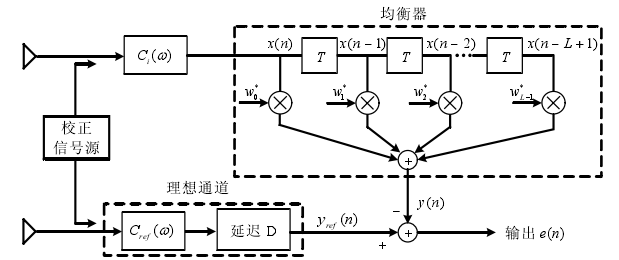

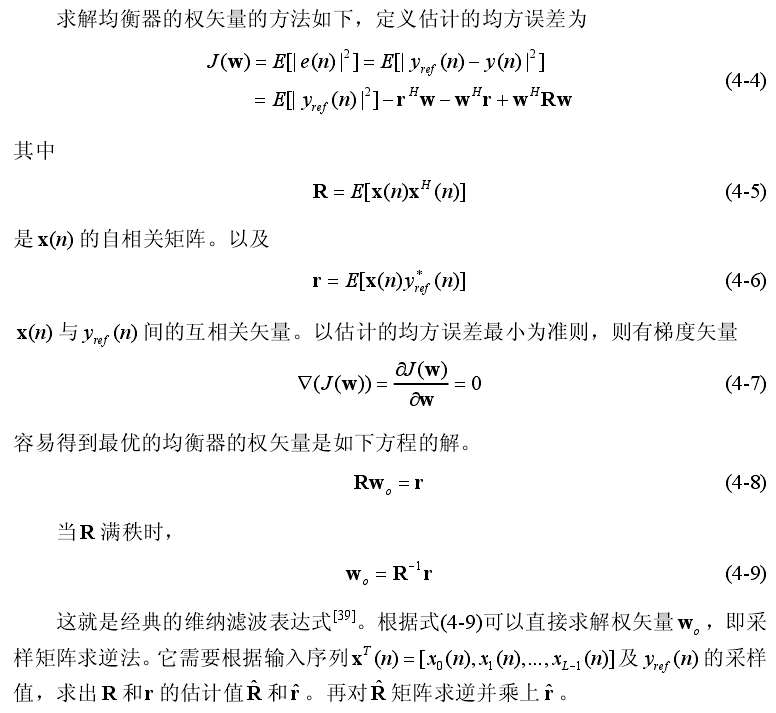

 clear;clc;close all

按照400Mhz采样构造一个-130Mhz~130Mhz的线性调频复信号作为信号输入

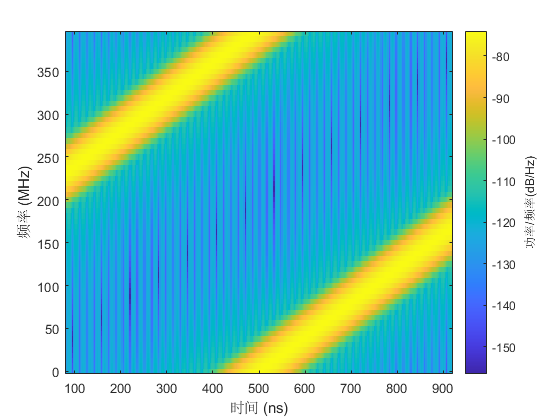

fs = 400e6;
waveform = phased.FMCWWaveform('SampleRate',fs,...
                              'SweepBandwidth',400e6,...
                              'SweepTime',1e-6,...
                              'SweepInterval','Symmetric');

sig = waveform();
spectrogram(sig,64,63,64,fs,'yaxis')

%-------------------------------------------------------------
LP_cali=LP_P90_S100_N101;                                        %需要矫正的通道
w = LP_cali.Numerator;
sig_cali = conv(w,sig);                                             %矫正的通道

f = @(x)cost_function(x,sig,sig_cali);

output_w = particleswarm(f,51,-ones(51,1),ones(51,1));

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


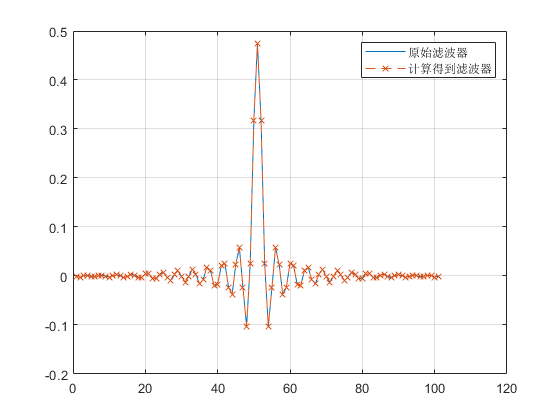

output_w = output_w(:);
output_w = [flipud(output_w(2:end));output_w];
sig_output = conv(output_w,sig);

figure(1)
plot(w);hold on;plot(output_w,'--x');hold off;grid on;legend('原始滤波器','计算得到滤波器')

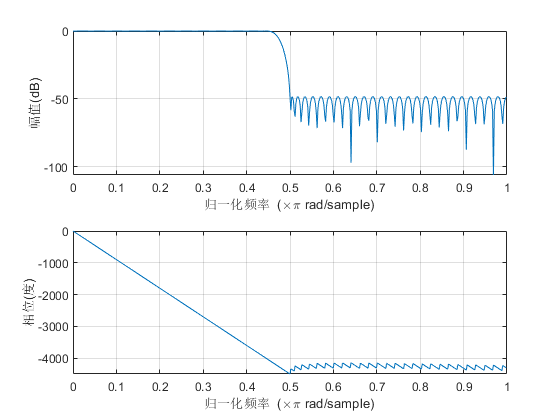

freqz(output_w)